## **VÝPOČET LAVALOVY DÝZY PRO PLYNY**

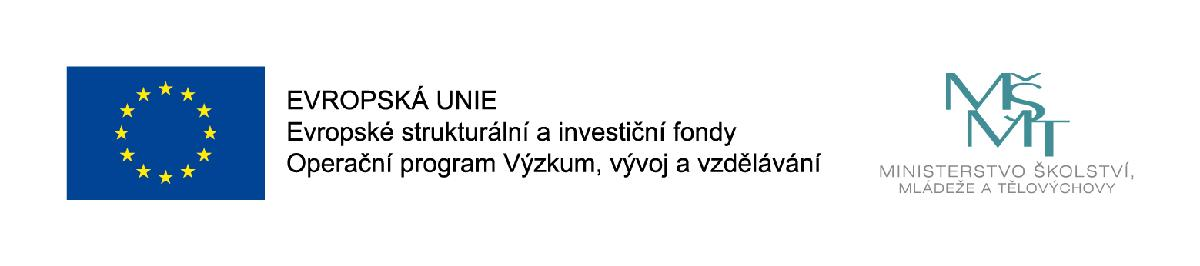

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

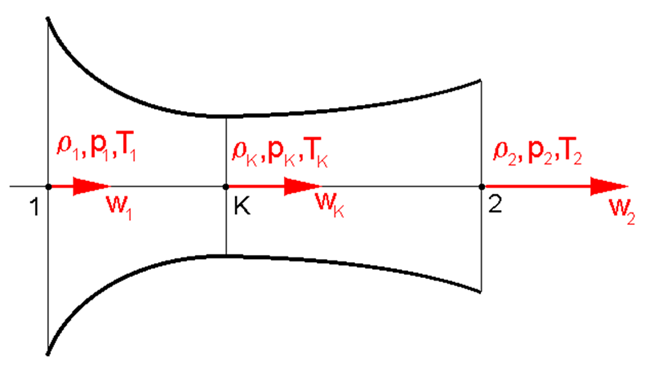

Body:

0 : místo s nulovou rychlostí, zásobník plynu

1: vstup plynu no dýzy, většinou se předpokládá, že 1 je totožné s 0

K: kritický bod, nejužší místo. Místo kde se dosahuje lokální rychlost zvuku

2: konec dýzy, expanze plynu do okoli, předpoklad tlak na konci dýzy je totožný s tlakem okolí

Kontrola nutnosti Lavalovy dýzy:


$$$\frac{{{p_K}}}{{{p_1}}}{\kern 1pt}  = {\kern 1pt} {\left( {\frac{2}{{\kappa  + 1}}} \right)^{\frac{\kappa }{{\kappa  - 1}}}} > {\kern 1pt} \frac{{{p_2}}}{{{p_1}}}$$$


Rychlosti:

$${w_k} = \sqrt {\frac{{2\kappa }}{{\kappa  - 1}}{p_1}{v_1} \left[ {1  - {{\left( {\frac{{{p_K}}}{{{p_1}}}} \right)} ^ {\frac{(\kappa  - 1)} 
{ \kappa }}}} \right] }} $$    varianta $${w_k} = \sqrt {\frac{{2\kappa }}{{\kappa  + 1}}{p_1}{v_1}  }} $$ varianta  $${w_k} = \sqrt {2 c_p \left(T_1-T_K)} $$

$${w_2} = \sqrt {\frac{{2\kappa }}{{\kappa  - 1}}{p_1}{v_1} \left[ {1  - {{\left( {\frac{{{p_2}}}{{{p_1}}}} \right)} ^ {\frac{(\kappa  - 1)} 
{ \kappa }}}} \right] }} $$  varianta  $${w_2} = \sqrt {2 c_p \left(T_1-T_2)} $$

Rovnice adiabaty:


$$${p_1v_1^\kappa} = {p_Kv_K^\kappa} = {p_2v_2^\kappa}$$$



$$${v_K} = {v_1}{\left( {\frac{{{p_1}}}{{{p_K}}}} \right)^{\frac{1}{\kappa }}}$$$
        
$$${v_2} = {v_1}{\left( {\frac{{{p_1}}}{{{p_2}}}} \right)^{\frac{1}{\kappa }}}$$$


Průřezy:


$$$\dot m = \frac{S_Kw_K} {v_K} = \frac{S_2w_2}{v_2}$$$


Délka (úhel rozšíření volíme):


$$$L = \frac{{{D_2} - {D_K}}}{{2 \cdot tg\,\alpha }}$$$


### Příklad

Navrhněte rozměry Lavalovy dýzy (tj. minimální průměr, výstupní průměr a délku nátrubku) pro hmotnostní výtok 10 kg/s kyslíku z plynojemu o přetlaku 2 MPa a teplotě 22 °C do prostředí o tlaku 1010 hPa. Rozšíření nátrubku volte 12°.

clear;
pbhPa = 1010;       % [hPa] 
p0MPa = 2.0;        % [MPa]
t0C = 22.0;         % [°C]
mdot = 10.0;        % [kg/s]
alfa2x = 12;        % [°]
M02 = 32;           % [kg/mol] 
kappa = 1.41;       % dvouatovový plyn

pb = hPa2Pa(pbhPa);
T_0 = C2K(t0C);
p_0 = MPa2Pa(p0MPa) + pb;       % Absolutní tlak
r = Rm/M02;
v_0 = r * T_0/p_0;      % Stavová rovnice
% Beta kritické
beta_kr = (2/(kappa+1))^(kappa/(kappa-1));

p_kr = p_0 * beta_kr;

cp = kappa/(kappa-1)*r;
v_kr = v_0 * (p_0/p_kr)^(1/kappa);  % kritický měrný objem
T_kr = p_kr * v_kr/r;

w_kr_1 = sqrt(2*kappa/(kappa+1)*r*T_0);   % Kritická rychlost
w_kr = sqrt(2*kappa/(kappa-1)*r*T_0*(1-(p_kr/p_0)^((kappa-1)/kappa))); % Kritická rychlost
w_kr_2 = sqrt(2*cp*(T_0-T_kr));  % Kritická rychlost

p_2 = pb;
beta = p_2/p_0;
v_2 = v_0 * (p_0/p_2)^(1/kappa);
T_2 = p_2 * v_2 / r;
w_2 = sqrt(2*kappa/(kappa-1)*r*T_0*(1-(p_2/p_0)^((kappa-1)/kappa)));
w_2_2 = sqrt(2*cp*(T_0-T_2));

S_kr = mdot * v_kr /w_kr;

S_kr = 0.0019

D_kr = sqrt(S_kr/pi*4);

D_kr = 0.0494

S_2 = mdot * v_2 /w_2;

S_2 = 0.0056

D_2 = sqrt(S_2/pi*4);

D_2 = 0.0848

L = (D_2-D_kr)/(2*tand(alfa2x/2));

L = 0.1682

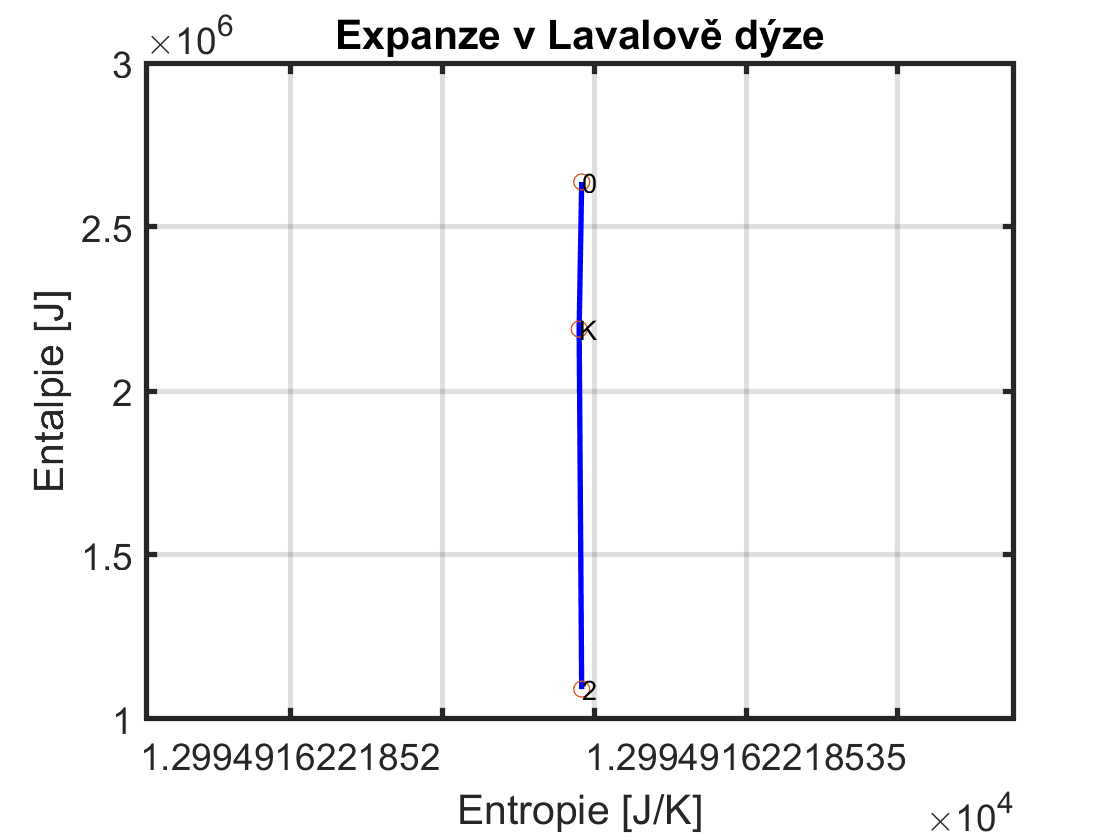

S(1)=mdot*cp*log(T_0)-mdot*r*log(p_0);
S(2)=mdot*cp*log(T_kr)-mdot*r*log(p_kr);
S(3)=mdot*cp*log(T_2)-mdot*r*log(p_2);
H(1)=mdot*cp*T_0;
H(2)=mdot*cp*T_kr;
H(3)=mdot*cp*T_2;

figure
plot(S,H,'-b','linewidth',2);
hold on
plot(S,H,'o');
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
title('Expanze v Lavalově dýze') 
xlabel('Entropie [J/K]') 
ylabel('Entalpie [J]') 
grid on;
text(S(1),H(1),'0'); 
text(S(2),H(2),'K'); 
text(S(3),H(3),'2'); 

fprintf('Beta : %.3f < Beta kritická  : %.3f  \n',beta,beta_kr);

Beta : 0.048 < Beta kritická  : 0.527  


fprintf('Rychlost kritická : %.1f m/s Rychlost maximální %.1f m/s \n',w_kr,w_2);

Rychlost kritická : 299.6 m/s Rychlost maximální 556.1 m/s 


fprintf('Rychlost kritická : %.1f m/s Rychlost maximální %.1f m/s \n',w_kr_2,w_2_2);

Rychlost kritická : 299.6 m/s Rychlost maximální 556.1 m/s 


fprintf('Nejmenší průměr : %.1f mm Největší průmer : %.1f mm Délka : %.1f mm \n',m2mm(D_kr),m2mm(D_2),m2mm(L));

Nejmenší průměr : 49.4 mm Největší průmer : 84.8 mm Délka : 168.2 mm 


### Vykreslení parametrů podél Lavalovy dýzy

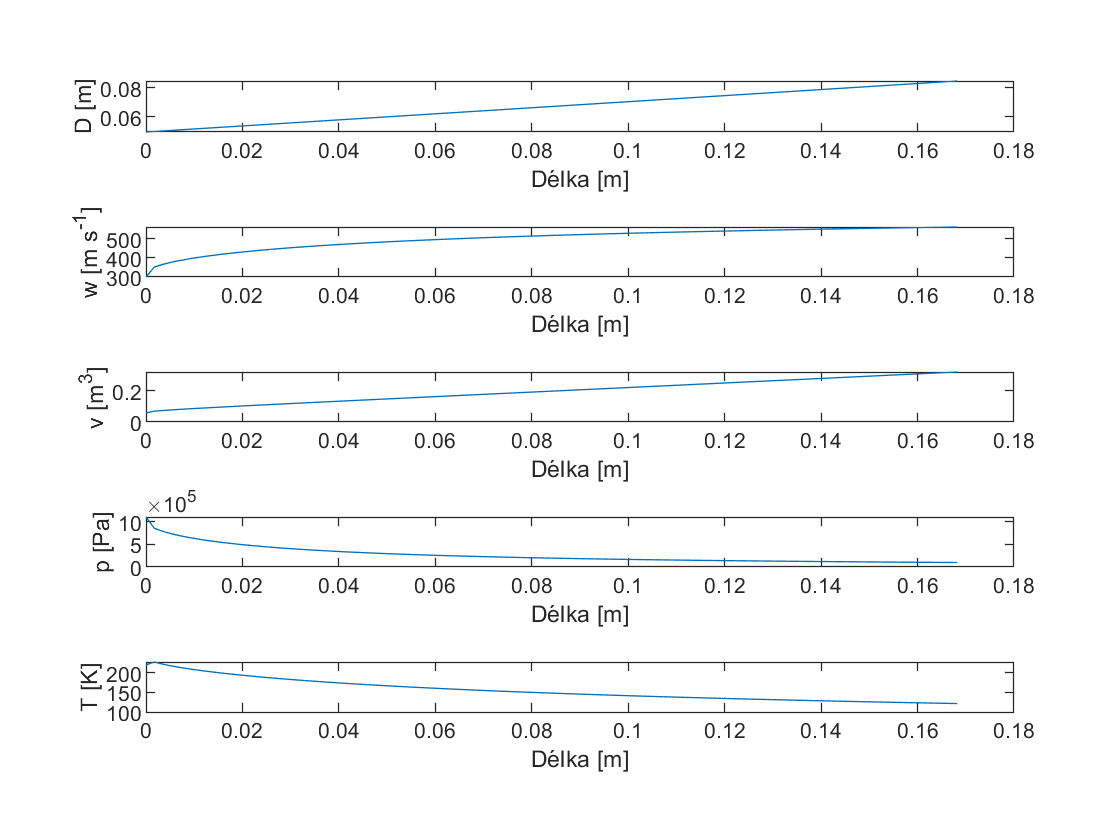

S = linspace(S_kr,S_2,100);
x = linspace(0,L,100);
DD = linspace(D_kr,D_2,100);

S_size=length(S);
w=zeros(S_size,1);
T=zeros(S_size,1);
p=zeros(S_size,1);
v=zeros(S_size,1);

m = mdot;
w(1)= w_kr;
T(1)=220;
p(1)=p_kr;
v(1)= v_kr;

% explicitní výpočet
for ii=1:(S_size-1)
    w(ii+1)=-(S(ii+1)-S(ii))/(S(ii))*w(ii)*1/(1-w(ii)^2/(kappa*r*T(ii)))+w(ii);
    v(ii+1)=(S(ii+1)*w(ii+1))/(m);
    p(ii+1)=p(ii)*(v(ii)/v(ii+1))^kappa;
    T(ii+1)=p(ii+1)*v(ii+1)/r;
end
figure;
subplot(5,1,1)
plot(x,DD)
xlabel('Délka [m]')
ylabel('D [m]')
subplot(5,1,2)
plot(x,w)
xlabel('Délka [m]')
ylabel('w [m s^{-1}]')
subplot(5,1,3)
plot(x,v)
xlabel('Délka [m]')
ylabel('v [m^{3}]')
subplot(5,1,4)
plot(x,p)
xlabel('Délka [m]')
ylabel('p [Pa]')
subplot(5,1,5)
plot(x,T)
xlabel('Délka [m]')
ylabel('T [K]')

### Příklad

Do Lavalovy dýzy proudí kysličník uhličitý  (CO2) o přetlaku 4,5 MPa , teplotě 820 °C a vytéká do atmosféry. Kritický průměr dýzy je 40 mm. Za jakou dobu proteče dýzou 50 kg plynu. Atmosférický tlak je 980 hPa.  Stanovte také kritickou rychlost, výtokovou rychlost a teplotu plynu v nejužším místě dýzy a v koncovém bodě.

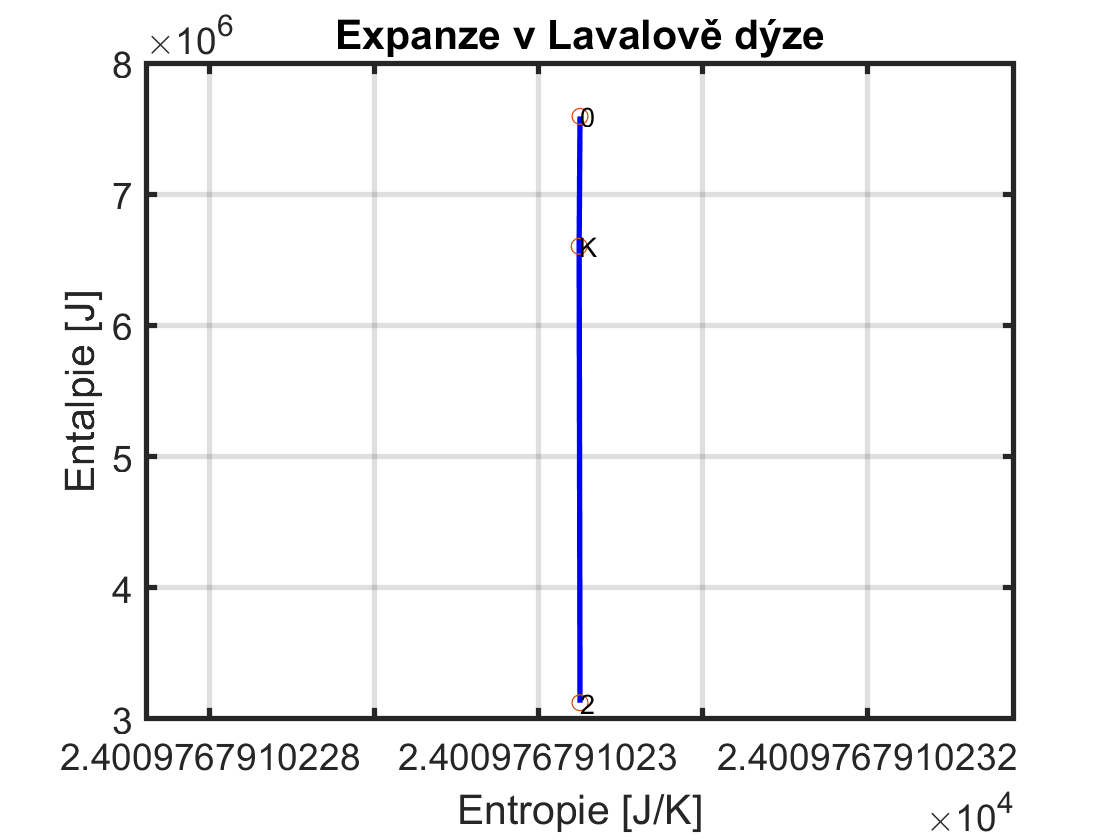

pbhPa = 980;        % [hPa] 
p0MPa = 4.5;        % [MPa]
t0C = 820.0;        % [°C]
mcelkem = 50.0;     % [kg]
MC02 = 44;          % [kg/mol] 
kappa = 1.3;        % tříatomový plyn
Dmm_kr = 40;        % [mm] kritický průměr
pb = hPa2Pa(pbhPa);
T_0 = C2K(t0C);
p_0 = MPa2Pa(p0MPa) + pb;       % Absolutní tlak
r = Rm/MC02;
v_0 = r * T_0/p_0;      % Stavová rovnice
% Beta kritické
beta_kr = (2/(kappa+1))^(kappa/(kappa-1));
p_kr = p_0 * beta_kr;

cp = kappa/(kappa-1)*r;
v_kr = v_0 * (p_0/p_kr)^(1/kappa);  % kritický měrný objem
T_kr = p_kr * v_kr/r;

w_kr_1 = sqrt(2*kappa/(kappa+1)*r*T_0);   % Kritická rychlost
w_kr = sqrt(2*kappa/(kappa-1)*r*T_0*(1-(p_kr/p_0)^((kappa-1)/kappa))); % Kritická rychlost
w_kr_2 = sqrt(2*cp*(T_0-T_kr));  % Kritická rychlost

p_2 = pb;
beta = p_2/p_0;
v_2 = v_0 * (p_0/p_2)^(1/kappa);
T_2 = p_2 * v_2 / r;
w_2 = sqrt(2*kappa/(kappa-1)*r*T_0*(1-(p_2/p_0)^((kappa-1)/kappa)));
w_2_2 = sqrt(2*cp*(T_0-T_2));

S_kr = pi * mm2m(Dmm_kr)^2/4.0;
mdot =  S_kr * w_kr /v_kr;

Tau = mcelkem/mdot;

S = zeros(3,1);
H = zeros(3,1);

S(1)=mdot*cp*log(T_0)-mdot*r*log(p_0);
S(2)=mdot*cp*log(T_kr)-mdot*r*log(p_kr);
S(3)=mdot*cp*log(T_2)-mdot*r*log(p_2);
H(1)=mdot*cp*T_0;
H(2)=mdot*cp*T_kr;
H(3)=mdot*cp*T_2;

figure
plot(S,H,'-b','linewidth',2);
hold on
plot(S,H,'o');
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
title('Expanze v Lavalově dýze') 
xlabel('Entropie [J/K]') 
ylabel('Entalpie [J]') 
grid on;
text(S(1),H(1),'0'); 
text(S(2),H(2),'K'); 
text(S(3),H(3),'2'); 

fprintf('Beta : %.3f < Beta kritická  : %.3f  \n',beta,beta_kr);

Beta : 0.021 < Beta kritická  : 0.546  


fprintf('Rychlost kritická : %.1f m/s Rychlost maximální %.1f m/s \n',w_kr,w_2);

Rychlost kritická : 483.2 m/s Rychlost maximální 1026.5 m/s 


fprintf('Rychlost kritická : %.1f m/s Rychlost maximální %.1f m/s \n',w_kr_2,w_2_2);

Rychlost kritická : 483.2 m/s Rychlost maximální 1026.5 m/s 


fprintf('Hmotnostní tok : %.3f kg/s Čas průtoku : %.1f s \n',mdot,Tau);

Hmotnostní tok : 8.483 kg/s Čas průtoku : 5.9 s 


### Lokální funkce 

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [m] = mm2m(mm)
m = mm/1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end

Převod

function [Pa] = MPa2Pa(MPa)
Pa = MPa*1e6;
end